# derive_equations_JR.m

Description: Symbolically derive equations related to the jumping robot, including the full nonlinear state-space dynamics.

Inputs: none

Outputs: none

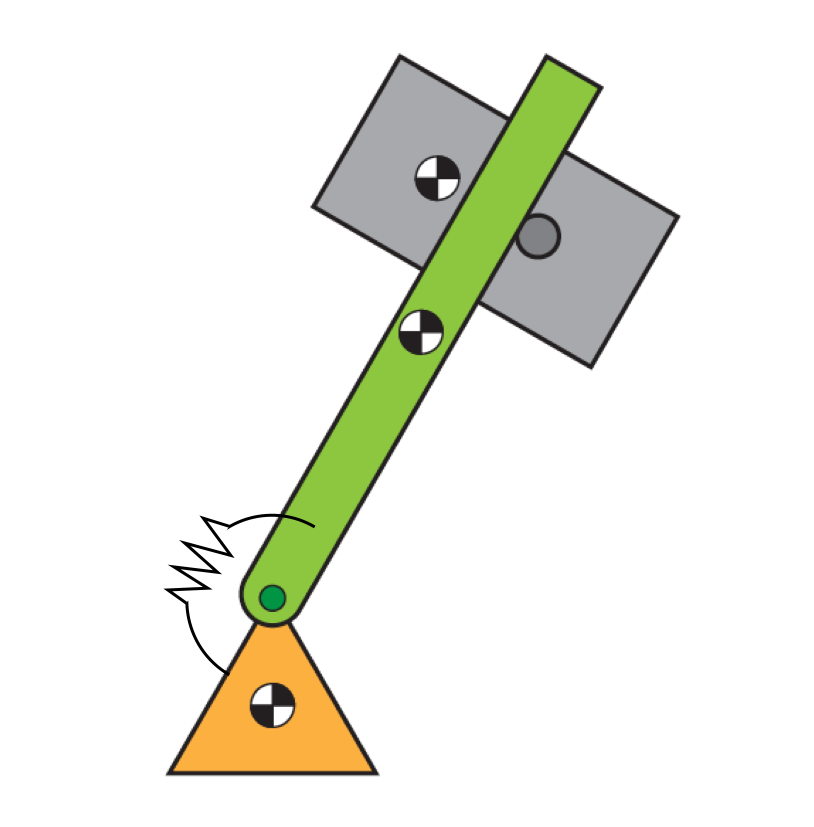

% Script Version:  derive_equations_JR_script.mxl
clear;
close all;
clc;

fprintf('Deriving jumping robot equations...\n');

## Variable definition

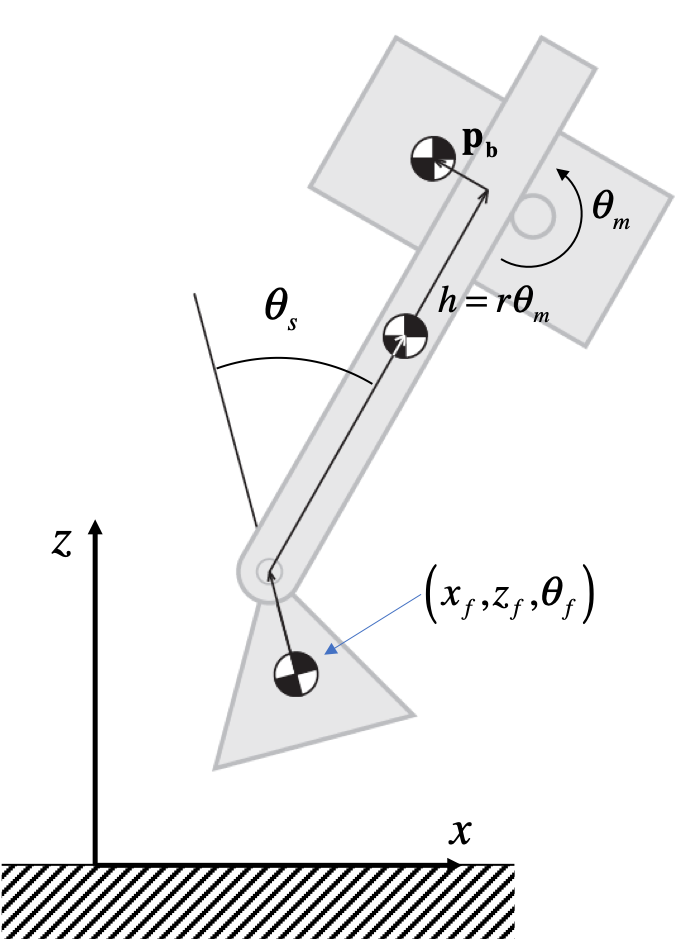 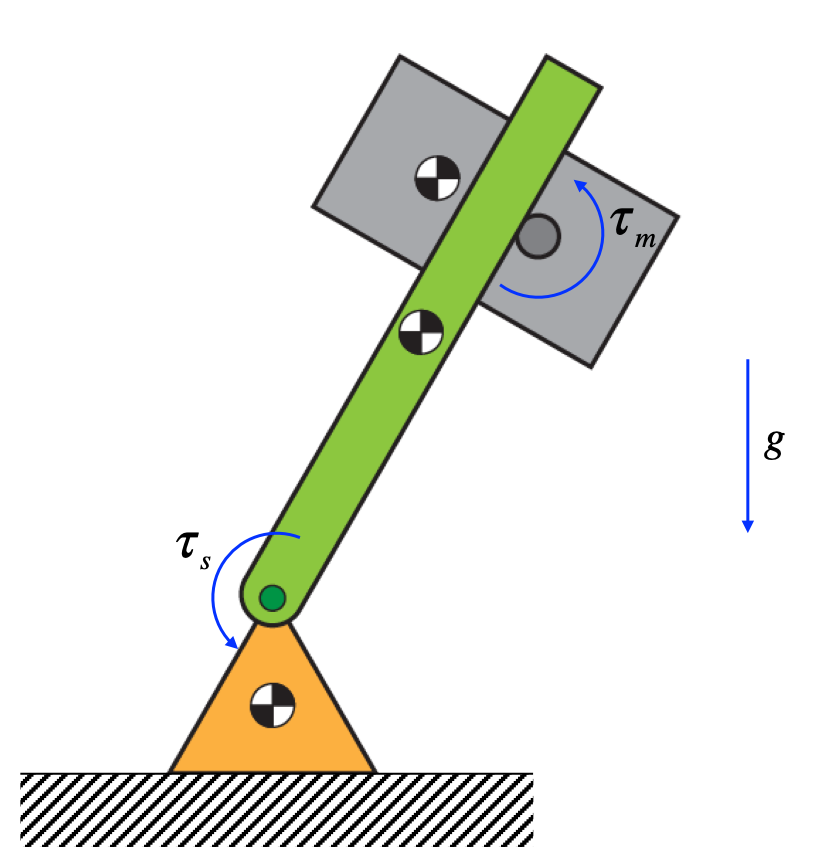

fprintf('\tInitializing generalized coordinates, velocities, accelerations, and forces...\n');

% Generalized coordinates:
% x_f:  horizontal displacement of foot CoM
% z_f:  vertical displacement of foot CoM
% theta_f: angle of the foot relative to ground; positive cw
% theta_s: angle of the spine relative to foot; positive cw
% theta_m: angle of the motor; positive ccw
syms x_f z_f theta_f theta_s theta_m real
q = [x_f; z_f; theta_f; theta_s; theta_m];

% Generalized velocities:
syms x_dot_f z_dot_f theta_dot_f theta_dot_s theta_dot_m real
q_dot = [x_dot_f; z_dot_f; theta_dot_f; theta_dot_s; theta_dot_m]

% Generalized accelerations:
syms x_ddot_f z_ddot_f theta_ddot_f theta_ddot_s theta_ddot_m real
q_ddot = [x_ddot_f; z_ddot_f; theta_ddot_f; theta_ddot_s; theta_ddot_m]

% Generalized forces:
% tau_s: torque at base of spine; positive cw
% tau_m: motor torque on body motor; positive ccw
syms tau_s tau_m real 
Q = [0; 0; 0; tau_s; tau_m];

fprintf('\t...done.\n');

## Inertial (and other) parameters

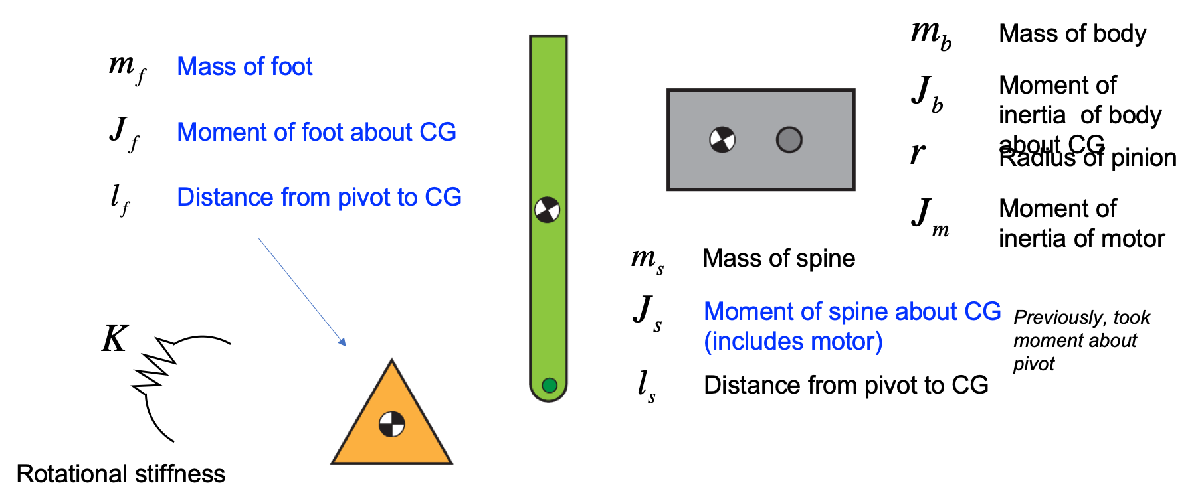

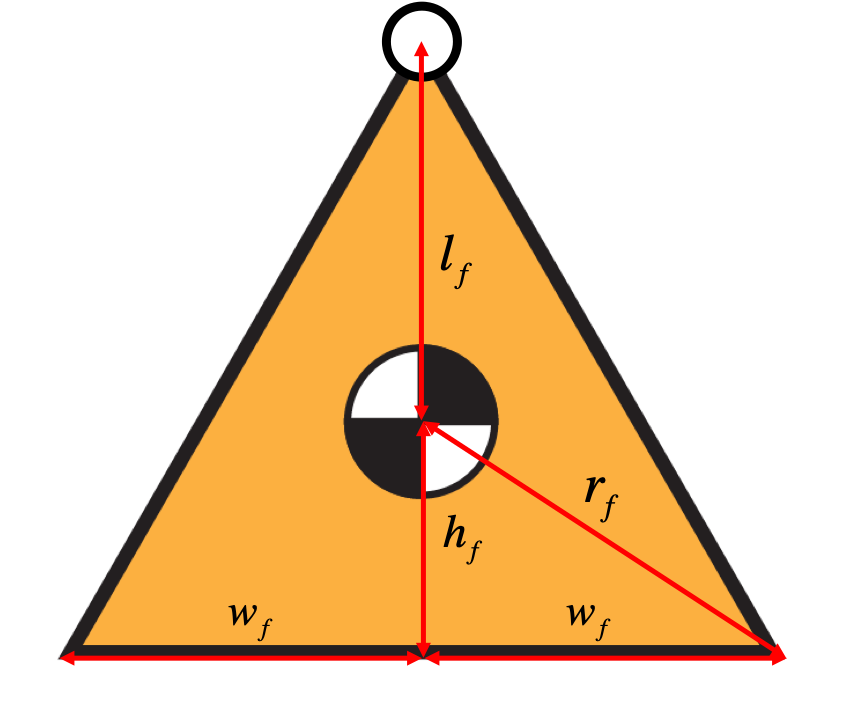

A couple of other parameters include h_b, the height of the body, and l_spine, the length of the spine.

fprintf('\tInitializing inertial (and other) parameters...\n');

% Mass of each body:
syms m_f m_s m_b real

% Rotational inertia of each component:
syms J_f J_s J_b J_m real

% Stiffness between sping and foot:
syms K real

% Geometry:
syms l_s p_b h_b r h_f w_f l_f l_spine real

% Other variables
g = sym('g','real'); % gravity
% t = sym('t','real'); % time

fprintf('\t...done.\n');

## Forward Kinematics

Here the goal is to find the CoM motion of the spine and body in terms of the generalized coordinates (the foot is trivial)

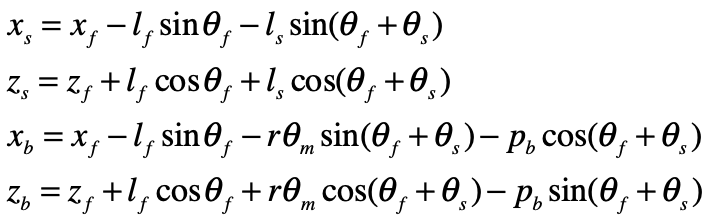

fprintf('\tInitializing kinematics variables...\n');

% x and z coordinates of the spine and body CoM:
syms x_s z_s x_b z_b real

x_s = x_f - l_f*sin(theta_f) - l_s*sin(theta_f + theta_s);
z_s = z_f + l_f*cos(theta_f) + l_s*cos(theta_f + theta_s);
x_b = x_f - l_f*sin(theta_f) - r*theta_m*sin(theta_f + theta_s) - p_b*cos(theta_f + theta_s);
z_b = z_f + l_f*cos(theta_f) + r*theta_m*cos(theta_f + theta_s) - p_b*sin(theta_f + theta_s);

% create 2x1 arrays to hold the CoM forward kinematics (FK) outputs:
FK_com_s = [x_s; z_s];
FK_com_b = [x_b; z_b];

% coordinates of the pivot and the spine tip to help animate
syms x_pivot z_pivot x_tip z_tip real

x_pivot = x_f - l_f*sin(theta_f);
z_pivot = z_f + l_f*cos(theta_f);
x_tip = x_f - l_f*sin(theta_f) - l_spine*sin(theta_f + theta_s);
z_tip = z_f + l_f*cos(theta_f) + l_spine*cos(theta_f + theta_s);

% create 2x1 arrays to hold the Visualization forward kinematics (FK) outputs:
FK_pivot = [x_pivot; z_pivot];
FK_tip = [x_tip; z_tip];

fprintf('\t...done.\n');
fprintf('\tGenerating forward kinematics equations...\n');

% generate MATLAB functions to compute all the FK outputs:
matlabFunction(FK_com_s,FK_com_b,'File','autogen_fk_com');
matlabFunction(FK_pivot,FK_tip,'File','autogen_fk_viz');
% Note: these autogenerated functions will make plotting/animation easier
% later. Could also help with some control tasks.
fprintf('\t...done.\n');

## Constraint Equations

Here we write out the three constraint equations that are in play when the foot is planted on the ground.  The constraints come from each bottom corner not penetrating the floor, and from the foot not slipping sideways

## 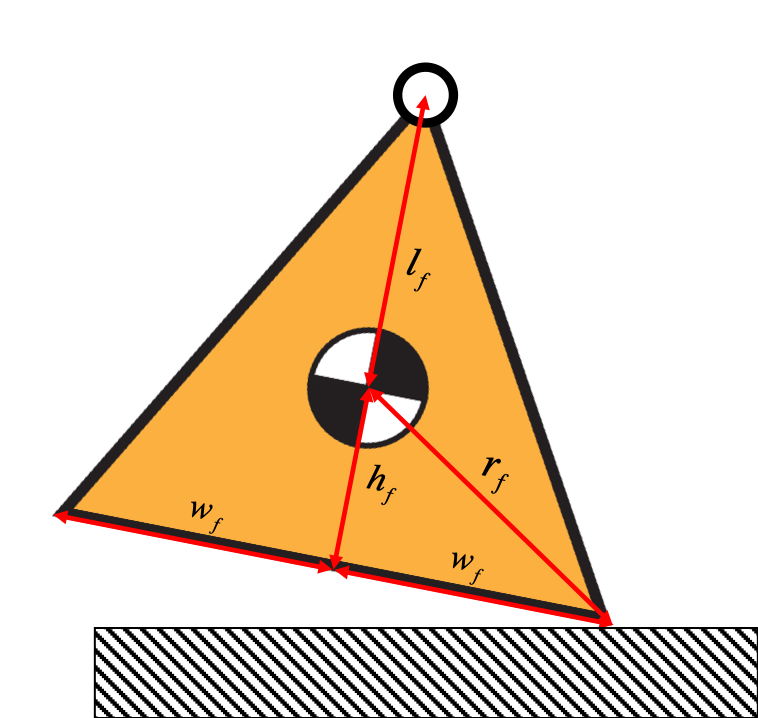

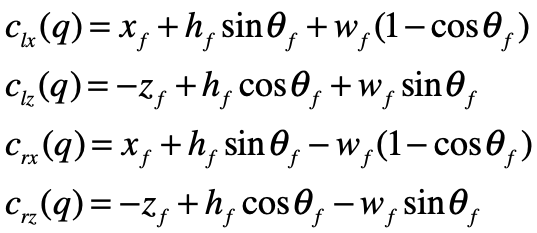

c1 is the left bottom corner.  Notice that this is different than what was in the lecture.  I added a fourth constraint equation.  Now, instead of a single equation for the x direction, we have one for each corner.  Normally, we will use only one.  It doesn't matter which one because they're redundant with one another.  If one foot lifts off, we'll then have two remaining constraint equations, and then we'll need to be sure to use the ones associated with the foot that remains on the ground.

We also have constraint equations that keep the body from flying off the top or bottom of the spine (this was absent in earlier versions, which led to some interesting simulation results!).  This constraint equations are:

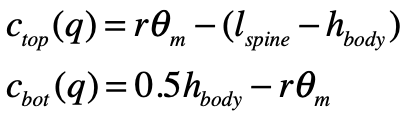

Like the z-axis foot constraints, these are actually unilateral, and should be written with an inequality (they must remain negative).  But we write them here as equalities to be consistent with the equations we will derive.  The inequality comes into play in the ode45 Events function.

fprintf('\tInitializing constraint variables...\n');

% six constraint variables:
syms c_lx c_lz c_rx c_rz c_top c_bot real

% bilateral
c_lx = x_f + h_f*sin(theta_f) + w_f*(1 - cos(theta_f));
c_rx = x_f + h_f*sin(theta_f) - w_f*(1 - cos(theta_f));

% unilateral
c_lz = -z_f + h_f*cos(theta_f) + w_f*sin(theta_f);
c_rz = -z_f + h_f*cos(theta_f) - w_f*sin(theta_f);
c_top = r*theta_m - l_spine + 0.5*h_b;
c_bot = 0.5*h_b - r*theta_m;

% create arrayx to hold constraints:
C_bilateral = [c_lx; c_rx];
C_unilateral = [c_lz; c_rz; c_top; c_bot];

fprintf('\t...done.\n');
fprintf('\tGenerating constraint equations...\n');

% generate MATLAB functions to compute all the constraints:
matlabFunction(C_bilateral,C_unilateral,'File','autogen_constraints');
fprintf('\t...done.\n');

## Derivatives

Here we take derivatives of both the forward kinematics and the constraint equations

fprintf('\tGenerating time derivatives of the kinematics equations...\n');

syms dFK_com_s dFK_com_b A_all H_clx H_clz H_crx H_crz real

% Body CoM velocities:
dFK_com_s = jacobian(FK_com_s,q)*q_dot
dFK_com_b = jacobian(FK_com_b,q)*q_dot

% Constraint equations first and second derivatives
A_bilateral = jacobian(C_bilateral,q)
A_unilateral = jacobian(C_unilateral,q)
H_clx = hessian(c_lx,q)
H_crx = hessian(c_rx,q)
H_clz = hessian(c_lz,q)
H_crz = hessian(c_rz,q)
H_ctop = hessian(c_top,q)
H_cbot = hessian(c_bot,q)

% generate MATLAB functions for the Jacobians and Hessians:
matlabFunction(dFK_com_s,dFK_com_b,'File','autogen_jacobians');
matlabFunction(A_bilateral,A_unilateral,H_clx,H_crx,H_clz,H_crz,H_ctop,H_cbot,'File','autogen_constraint_derivatives');

fprintf('\t...done.\n');

## Kinetic energy

Sum up:

- Foot translational

- Foot rotational

- Spine translational

- Spine rotational

- Body translational

- Body rotational

- Motor rotational

fprintf('\tGenerating kinetic energy equation...\n');

syms ke_f ke_s ke_b KE real

% kinetic energy of each body:
ke_f = 0.5*J_f*theta_dot_f^2 + 0.5*m_f*(x_dot_f^2 + z_dot_f^2);
ke_s = 0.5*J_s*(theta_dot_f + theta_dot_s)^2 + 0.5*m_s*(dFK_com_s'*dFK_com_s);
ke_b = 0.5*J_b*(theta_dot_f + theta_dot_s)^2 + 0.5*m_b*(dFK_com_b'*dFK_com_b) + 0.5*J_m*(theta_dot_m + theta_dot_f + theta_dot_s)^2;

% total kinetic energy:
KE = ke_f + ke_s + ke_b

fprintf('\t...done.\n');

## Potential energy

Sum up:

- Gravitational potential of foot

- Gravitational potential of spine

- Gravitational potential of body

- Spring

Note:  does not include virtual work done by constraints

fprintf('\tGenerating potential energy equation...\n');

syms pe_f pe_s pe_b pe_spring real

% potential energy of each body:
pe_f = m_f*g*(z_f - h_f);
pe_s = m_s*g*(z_s - l_s - l_f - h_f);
pe_b = m_b*g*(z_b - l_f - h_f);
pe_spring = 0.5*K*theta_s^2;

% total potential energy:
PE = pe_f + pe_s + pe_b + pe_spring

fprintf('\t...done.\n');

## Euler-Lagrange equations

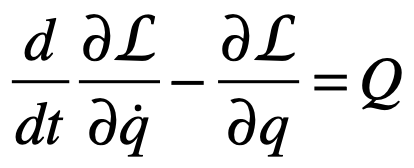

fprintf('\tGenerating Euler-Lagrange equations of motion...\n')

% Variable initializations:
del_L_del_qdot = sym('del_L_del_qdot',[numel(q),1],'real'); % del L/del q_dot
ELeq_term1  = sym('ELeq_term1',[numel(q),1],'real'); % d(del L/del dq)/dt
ELeq_term2  = sym('ELeq_term2',[numel(q),1],'real'); % del L/del q

del_L_del_qdot = jacobian(KE,q_dot)';
ELeq_term1 = simplify(jacobian(del_L_del_qdot,[q;q_dot])*[q_dot;q_ddot])
ELeq_term2 = simplify(jacobian((KE-PE),q))'
% Note: no constraint forces yet

fprintf('\t...done.\n')

## Finding the mass matrix and H(q,q_dot)

Note: the highest order derivative that shows up in the Euler-Lagrange Equations is second:  q_ddot  (accelerations).  Our goal is to obtain equations for q_ddot in terms of the state q, state derivatives q_dot, and generalized forces (i.e., the motor torques) Q.  These equations can then be integrated forward in time.  Fortunately, the accelerations always show up linearly and the matrix that multiplies them, the "mass matrix" is guaranteed to be invertible:

      M(q)*q_ddot + H(q,q_dot) = Q

Note that this equation is a generalization of F=ma. It represents the *inverse* dynamics, mapping positions, velocities, and accelerations of the joints to forces or torques (depending on the nature of each joint).

Important note:  there is additional structure in H that is often important to know about.  We won't go into that here.

fprintf('\tSolving for the mass matrix...\n');

M = sym('M',[numel(q),numel(q)],'real');
H = sym('H',[numel(q),1],'real');

M = simplify(jacobian(del_L_del_qdot,q_dot))
H = simplify(jacobian(del_L_del_qdot,q)*q_dot - ELeq_term2)

fprintf('\t\t...done building M and H.\n');


## Finding the inverse mass matrix

Note: we need inv(M) to compute the fwd. dynamics and therefore the state-space dynamics (see below), so to ease computation cost we derive inv(M) symbolically here and autogenerate a dedicated MATLAB function for evaluating it.


% compute and store inv(M):
fprintf('\t\tComputing inv(M)...\n')
Minv = sym('Minv',[numel(q),numel(q)],'real');
Minv = simplify(inv(M))
fprintf('\t\t...done.\n')

fprintf('\t\tGenerating MATLAB functions...\n');
matlabFunction(M,'File','autogen_mass_matrix');
matlabFunction(Minv,'File','autogen_inverse_mass_matrix');
matlabFunction(H,'File','autogen_H_eom');
fprintf('\t\t...done.\n');

## Done!

fprintf('...done deriving cart-pendulum equations.\n');
